## The impact of the EU-ETS on unemployment in France

### 0. Housekeeping

clear;
close all;

### 1. Data Importation 

Import Data Series:

- `GDP: OECD/QNA/FRA.B1_GE.CQRSA.Q`

- `Inflation: OECD/QNA/FRA.B1_GE.DNBSA.Q`

- `Unemployment: OECD/MEI/FRA.LRUN64TT.STSA.Q`

`Every serie is SA.`

% GDP, deflator, unemployment
[output,~,T] = call_dbnomics('OECD/QNA/FRA.B1_GE.CQRSA.Q','OECD/QNA/FRA.B1_GE.DNBSA.Q', 'OECD/MEI/FRA.LRUN64TT.STSA.Q');

### 2. Data treatment

Drop Na values and get index

idx = find(~isnan(sum(output(:,2:end),2)));
output = output(idx,:);
T = T(idx);

Normalize to 2015 prices

id2015 = find(T==2015);
def = output(:,3)/output(id2015,3);

### 3. Create variables of interest

gy_obs  = diff(log(output(:,2)./(def))); % Output growth
pi_obs  = diff(log(def)); % Inflation rate
u_obs = diff(log(output(:,4))); % Unemployment rate
T = T(2:end);

### 4. Test stationnarity

1 means that we reject null hypothesis (ADF = 1 => stationnarity ; KPSS = 1 => non-stationnarity)

GDP growth: stationnary

[h,pValue,stat,cValue] = adftest(gy_obs)

h = logical
   1


pValue = 1.0000e-03

stat = -11.8099

cValue = -1.9446

[h,pValue,stat,cValue] = kpsstest(gy_obs)

h = logical
   0


pValue = 0.1000

stat = 0.0139

cValue = 0.1460

Inflation: non-stationnary

[h,pValue,stat,cValue] = adftest(pi_obs)

h = logical
   1


pValue = 1.0000e-03

stat = -7.7933

cValue = -1.9446

[h,pValue,stat,cValue] = kpsstest(pi_obs) %pval = 1% => probablement car tendance haussière en fin de série

h = logical
   1


pValue = 0.0100

stat = 0.2228

cValue = 0.1460

Unemployment: non-stationnary

[h,pValue,stat,cValue] = adftest(u_obs)

h = logical
   1


pValue = 1.0000e-03

stat = -10.0434

cValue = -1.9446

[h,pValue,stat,cValue] = kpsstest(u_obs)

h = logical
   0


pValue = 0.1000

stat = 0.0623

cValue = 0.1460

### 5. Plot variables

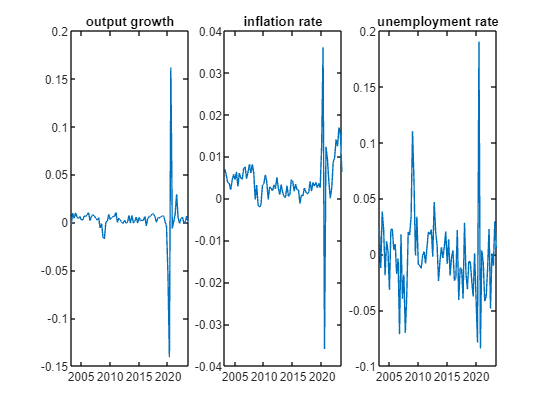

figure;
subplot(1,3,1)
plot(T,gy_obs)
xlim([min(T) max(T)]);
title('output growth')
subplot(1,3,2)
plot(T,pi_obs)
xlim([min(T) max(T)]);
title('inflation growth')
subplot(1,3,3)
plot(T,u_obs)
xlim([min(T) max(T)]);
title('unemployment growth')

### 6. Save variables in a matrix 

save myobs T gy_obs pi_obs u_obs;